# 演習12-2 odeによる人工衛星の軌道計算 

実行すれば動作する．

y0の値を変えると軌道が変化する．

例： y方向の速度を大きくしてみる．

% 地球の描画 
clf
hold on;
radius = 6.4E06;
[xs,ys,zs] = sphere(50);          % create a sphere 
xr=xs*radius;
yr=ys*radius;
zr=zs*radius;
% s = surface(x,y,z);     　% plot spherical surface
s = surface(xr,yr,zr);     % plot spherical surface
load topo topo topomap1    % load data 
whos('topo','topomap1')

  Name            Size              Bytes  Class     Attributes

  topo          180x360            518400  double              
  topomap1       64x3                1536  double              



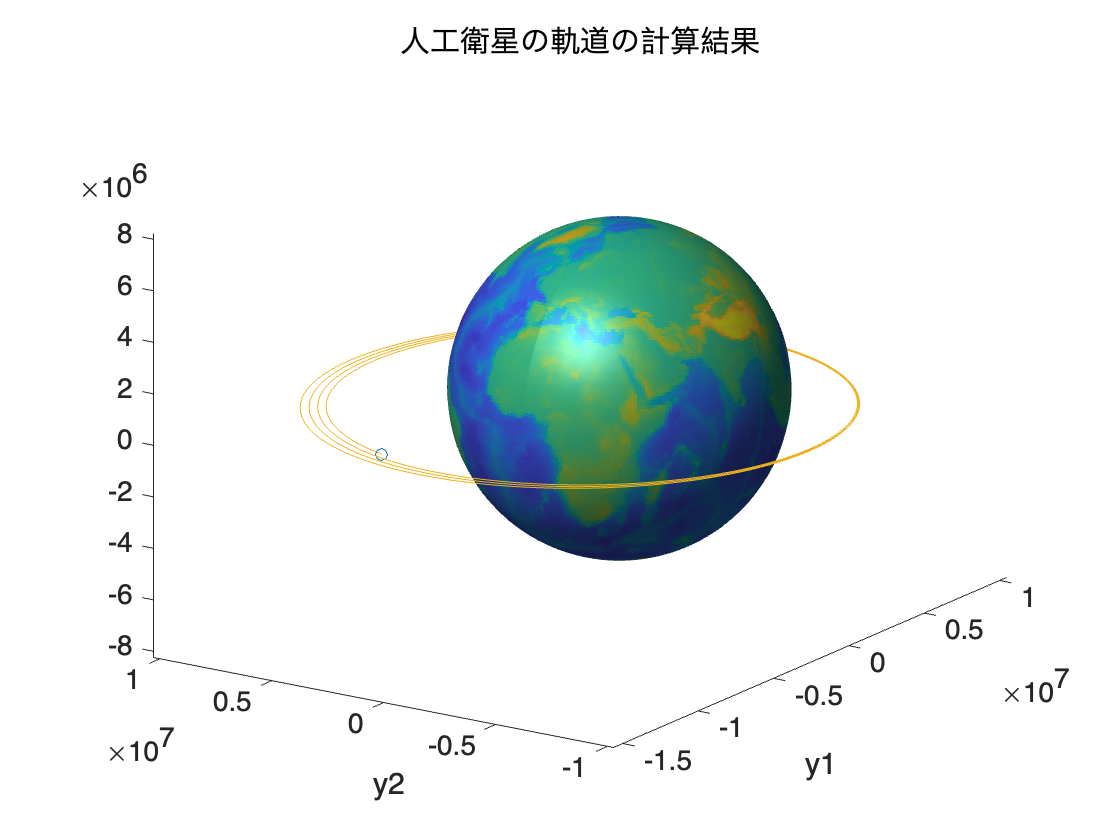

s.CData = topo;                % set color data to topographic data
s.FaceColor = 'texturemap';    % use texture mapping
s.EdgeColor = 'none';          % remove edges
s.FaceLighting = 'gouraud';    % preferred lighting for curved surfaces
s.SpecularStrength = 0.4;      % change the strength of the reflected light

light('Position',[-1 0 1])     % add a light

axis equal on                  % set axis to equal and draw axis
view([-30,30])                 % set the viewing angle

% 初期位置
y0=[8.0E+6; % x座標 地表から1600km 　(地球の半径 6400km)
    0;         % x方向の速度 0m/s
    0;         % y座標
    7.9E+3];   % y方向の速度
% (第１宇宙速度　7.9 km/s)
% (第２宇宙速度  11.2 km/s)
% 地球の半径 6400km
radius = 6.4E06;

% 0秒からhours時間の軌道を計算
t0=0.0;
hours=10;
t=0:30:3600*hours;
format longE;
% odeで微分方程式を解く
[t,y]=ode45(@satellite,t,y0);

% グラフ作成
% 微分方程式の解グラフ
graph = gca();
% comet(y(:,1),y(:,3),0.1);
y3=zeros(size(y,1),1);
comet3(y(:,1),y(:,3),y3,0.1);
% legend('ode45');
% viscircles([0,0],radius);
graph.FontSize =14;
graph.XAxisLocation = "origin";  % x軸の場所指定
graph.YAxisLocation = "origin";  % x軸の場所指定
xlabel('y1');    % x軸ラベル
ylabel('y2');    % y軸ラベル
title('人工衛星の軌道の計算結果');

hold off;
view([-56 17])

# ファイルの最後に関数定義を記述

連立微分方程式satelliteを定義してode45に引き渡す

function ydash=satellite(~,y)
% 人工衛星の微分方程式
% 万有引力定数
G=6.67E-11;
% 地球の質量　(kg)
M=6.0E+24;
% 衛星の距離(m)
r=sqrt(y(1)^2+y(3)^2);
% x方向の速度
ydash1=y(2);
% x方向の加速度
ydash2=-G*M*y(1)/r^3;
% y方向の速度
ydash3=y(4);
% y方向の加速度
ydash4=-G*M*y(3)/r^3;
ydash=[ydash1;ydash2;ydash3;ydash4];
end